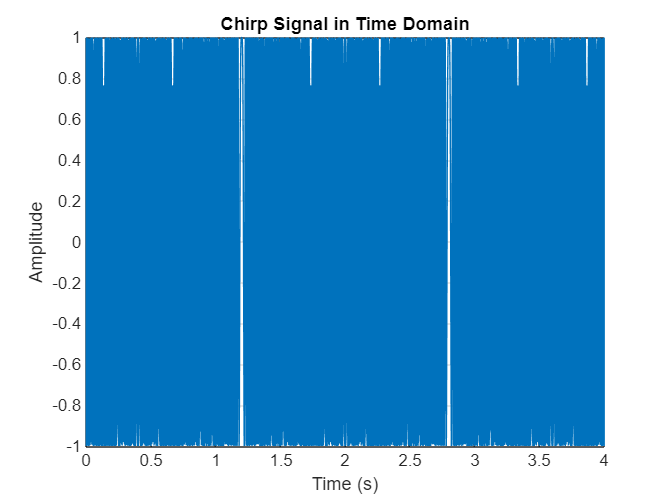

%(a) What happens when we make a signal that “chirps” up to a very high frequency, and the instantaneous frequency goes past half the sampling rate? 
% Generate a chirp signal that starts at 1000Hz when t D0s, and chirps up to 11;000Hz, at t D 4s. Use fs D4000Hz. 
% Determine the parameters needed in (1).

% Given parameters
f_s = 4000;             % Sampling frequency in Hz
tStart = 0;             % Start time in seconds
tStop = 4;              % Stop time in seconds
f1 = 1000;              % Starting frequency in Hz at t = 0 s
f2 = 11000;             % Ending frequency in Hz at t = 4 s

% Time vector
t = tStart:(1/f_s):tStop;  % Time vector from tStart to tStop with sampling interval 1/f_s

% Calculate slope parameter (mu)
mu = (f2 - f1) / (2 * (tStop - tStart));

% Phase calculation
phi = 2 * pi * mu * t.^2 + 2 * pi * f1 * t;

% Generate the chirp signal
chirp_signal = cos(phi);

% Plot the chirp signal
figure;
plot(t, chirp_signal);
title('Chirp Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

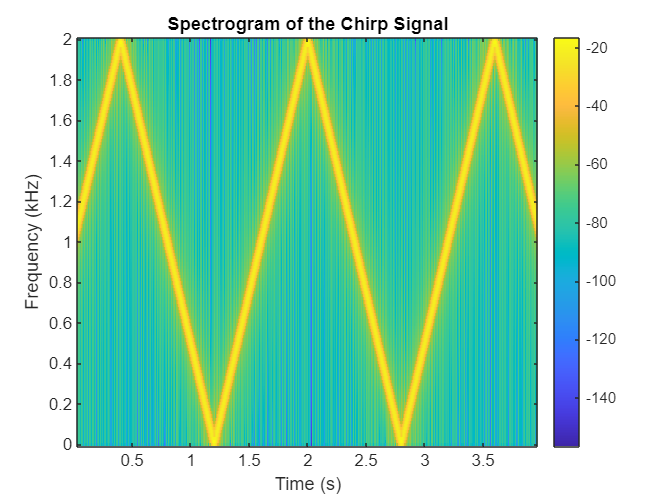


% Plot the spectrogram of the chirp signal
figure;
spectrogram(chirp_signal, 256, 250, 256, f_s, 'yaxis');
title('Spectrogram of the Chirp Signal');
xlabel('Time (s)');
ylabel('Frequency (kHz)');
colorbar;

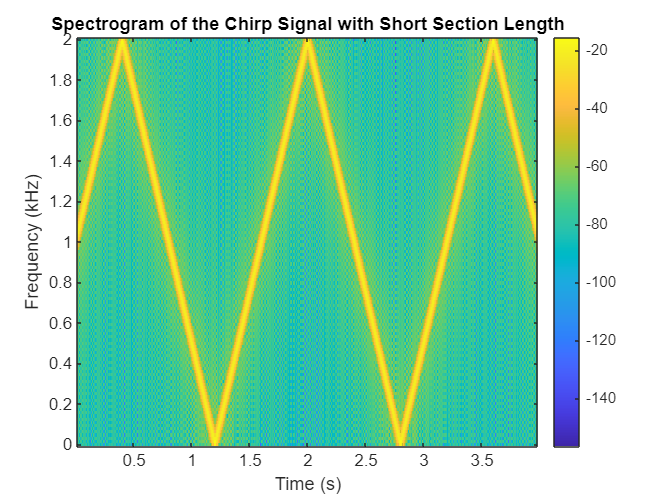


% What Happens When Frequency Exceeds Half the Sampling Rate?
% When the instantaneous frequency exceeds half the sampling rate (i.e., 2000 Hz in this case), aliasing occurs.
% Aliasing is a phenomenon where high-frequency components appear as lower frequencies. 
% In the spectrogram,  you will notice that once the chirp frequency exceeds 2000Hz, 
% it folds back into the frequency range below  2000Hz, creating mirrored frequency components.
% This results in distortion because the true frequency of the signal is not correctly represented in the sampled signal.

% (b) Generate the chirp signal in MATLAB and make a spectrogram with a short section length, LSECT, 
% to verify that you have the correct starting and ending frequencies.2 For your chosen LSECT, 
% determine the section duration TSECT in secs

% Spectrogram parameters
L_SECT = 128;  % Section length (number of samples per segment)
overlap = L_SECT - 10;  % Overlap of sections, chosen to provide smoother transitions
nfft = 256;  % Number of FFT points

% Plot the spectrogram of the chirp signal
figure;
spectrogram(chirp_signal, L_SECT, overlap, nfft, f_s, 'yaxis');
title('Spectrogram of the Chirp Signal with Short Section Length');
xlabel('Time (s)');
ylabel('Frequency (kHz)');
colorbar;


% Calculate section duration (T_SECT) in seconds
T_SECT = L_SECT / f_s;
disp(['Section duration T_SECT: ', num2str(T_SECT), ' seconds']);

Section duration T_SECT: 0.032 seconds



% (c) Explain why the instantaneous frequency seen in the spectrogram is goes up and down between zero and fs=2, i.e., 
% it does not chirp up to 11,000Hz. 
% There are two effects that should be accounted for in your explanation. 
% Note: If possible listen to the signal to verify that the spectrogram is faithfully representing the audio signal that you hear.

% . Aliasing Effect
% The sampling frequency is 4000 Hz, which means the Nyquist frequency is: 2000 Hz
% When the instantaneous frequency of the chirp exceeds the Nyquist frequency, aliasing occurs.
% Aliasing is the phenomenon where high frequencies are misrepresented as lower frequencies 
% when sampled at a rate that is insufficient to capture them accurately.
% In the case of this chirp signal: As the frequency of the chirp exceeds 2000Hz, 
% it is folded back into the lower frequency range (below the Nyquist frequency).
% This folding effect causes the frequency to appear to go down once it exceeds 2000Hz, 
% resulting in the up and down pattern seen in the spectrogram.
% This behavior is consistent with the aliasing theorem, which states that frequencies above 
% the Nyquist limit appear at incorrect, lower frequencies in the sampled signal.

% 2. Periodic Nature of Frequency Representation in the Spectrogram
% The Discrete Fourier Transform (DFT), which is used in calculating the spectrogram, treats frequency content as periodic.
% The frequency axis is considered to be periodic, with the range extending from 0 to f_s
% but practically folding at f_s/2.
% Frequencies between 0 and f s/2 are represented correctly.
% Frequencies beyond f_s/2 (up to f_s) are aliased and appear as if they are in the range 0 to f s/2.
% This periodic folding creates a mirror effect in the spectrogram.
% Therefore, the instantaneous frequency appears to go back down after reaching f s/2. 
% This is a direct result of how the DFT operates and how the spectrogram interprets frequencies beyond the Nyquist frequenc
